format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)

**6/89**,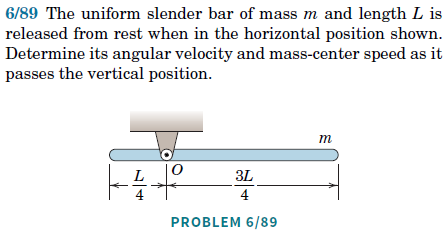

syms L_sym m_sym omega_2_sym g_sym

m = m_sym * u.kg; %masse
L = L_sym * u.m; %længden af emnet
d = L/4; % afstanden imellem masse midtpunkt og vores udregningspunkt

I = 1/12 * m * L^2 %+ d^2*m %slender rod i tyngde punktet + flytning 

$$I = \frac{{L_{\mathrm{sym}}}^{2}\,m_{\mathrm{sym}}}{12}\,\mathrm{kg}\,m^{2}$$

%se apendix D i dynamisk
s = L/4;
g = g_sym * u.m / u.s^2; %9.82 * u.m / u.s^2; 

%%%%%%% side 1  %%%%%%%%
v_1 = 0 * u.m/u.s; % translatorisk ahstighed
omega_1 = 0 % rotations hastighed

omega_1 =      0



T_1 = 1/2 * m * v_1^2 + 1/2 * I * omega_1^2

$$T\_1 = 0$$


V_1 = m*g*s

$$V\_1 = \frac{L_{\mathrm{sym}}\,g_{\mathrm{sym}}\,m_{\mathrm{sym}}}{4}\,\frac{\mathrm{kg}\,m^{2}}{s^{2}}$$


%%%%%%% side 2  %%%%%%%%


% omega_2 =
v_2 = omega_2_sym * s %kan udtrykkes om en hastighed * arm

$$v\_2 = \frac{L_{\mathrm{sym}}\,\omega_{2,\mathrm{sym}}}{4}\,m$$


T_2 = 1/2 * m * v_2^2 + 1/2 * I * omega_2_sym^2 % 1/2 * m * v_2^2 + 

$$T\_2 = \frac{7\,{L_{\mathrm{sym}}}^{2}\,m_{\mathrm{sym}}\,{\omega_{2,\mathrm{sym}}}^{2}}{96}\,\mathrm{kg}\,m^{2}$$



%%%%%%% udregning  %%%%%%%%
eq = T_1 + V_1 == T_2

$$eq = \frac{L_{\mathrm{sym}}\,g_{\mathrm{sym}}\,m_{\mathrm{sym}}}{4}\,\frac{\mathrm{kg}\,m^{2}}{s^{2}}=\frac{7\,{L_{\mathrm{sym}}}^{2}\,m_{\mathrm{sym}}\,{\omega_{2,\mathrm{sym}}}^{2}}{96}\,\mathrm{kg}\,m^{2}$$


assume([omega_2_sym,g],'positive')
omega_2 = solve(eq, omega_2_sym)

$$omega\_2 = \frac{2\,\sqrt{6}\,\sqrt{7}\,\sqrt{g_{\mathrm{sym}}}}{7\,\sqrt{L_{\mathrm{sym}}}}\,\frac{1}{s}$$

omega_2_ = vpa(unitConvert(omega_2, 1/u.s), 4) 

$$omega\_2\_ = \frac{1.852\,\sqrt{g_{\mathrm{sym}}}}{\sqrt{L_{\mathrm{sym}}}}\,\frac{1}{s}$$


tjek_omega = sqrt(24/7) * sqrt(g_sym /L_sym)

$$tjek\_omega = \frac{2\,\sqrt{6}\,\sqrt{7}\,\sqrt{g_{\mathrm{sym}}}\,\sqrt{\frac{1}{L_{\mathrm{sym}}}}}{7}$$

tjek_omega_ = vpa(sqrt(24/7), 4)

$$tjek\_omega\_ = 1.852$$


v_2 = vpa(omega_2 * s, 4 )

$$v\_2 = 0.4629\,\sqrt{L_{\mathrm{sym}}}\,\sqrt{g_{\mathrm{sym}}}\,\frac{m}{s}$$

tjek_v = vpa(sqrt(3/14), 4)

$$tjek\_v = 0.4629$$

6/90, 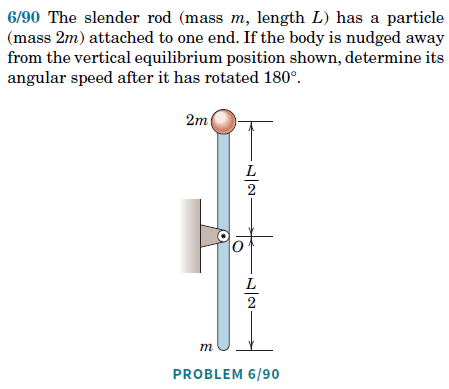

**6/91**,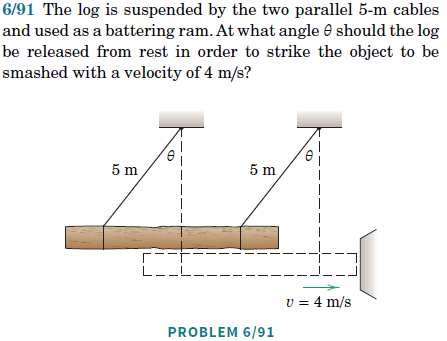


$$m \cdot g \cdot d = \frac{1}{2} \cdot m \cdot v^2$$


$d = 5m - \cos(\theta) \cdot 5m$ Højden der trækkes potentiel engergi fra

clear
format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)
syms L_sym m_sym g_sym theta_sym
g = 9.82 * u.m / u.s^2;
v = 4 * u.m / u.s;
theta = vpa(acosd(1 - v^2/(2*g * 5*u.m)), 4)

$$theta = 33.17$$

 **6/92**, 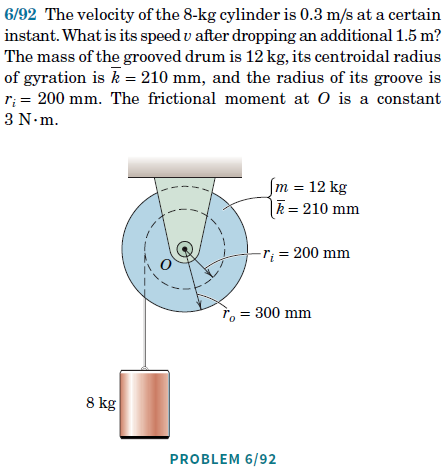

Her er en fejl. Da det der ikke er brug **radius og gyration**

syms v_2_sym
% assume(v_2_sym,'positive')

m_cyl = 8 * u.kg;
m_barrel = 12 * u.kg

$$m\_barrel = 12\,\mathrm{kg}$$

v_1 = 0.3 * u.m/u.s;
R_1 = 0.2 * u.m;
R_2 = 0.3 * u.m;
d = 1.5 *u.m

$$d = \frac{3}{2}\,m$$

g = 9.82 *u.m / u.s^2

$$g = \frac{491}{50}\,\frac{m}{s^{2}}$$


I = 1/2 * m_barrel * (R_1^2 + R_2^2)

$$I = \frac{39}{50}\,\mathrm{kg}\,m^{2}$$

% omega_1 = v_1 / R_1
% alpha = omega_1^2 *r_1

T_frik = 3 * u.N * u.m

$$T\_frik = 3\,N\,m$$

T = unitConvert(m_cyl * g * R_1, u.N * u.m)

$$T = \frac{1964}{125}\,N\,m$$

T_ = vpa(T, 4)

$$T\_ = 15.71\,N\,m$$

omega_2 = (v_2_sym  * u.m / u.s) / R_1;

omega_1 = v_1 / R_1;

displayFormula("F = K^2*A")
eq = unitConvert(1/2 * m_cyl * v_1^2 + 1/2 * I * omega_1^2 - T_frik + m_cyl * g * d, u.J) ==...
    unitConvert(1/2 * m_cyl * (v_2_sym * u.m / u.s)^2 + 1/2 * I * omega_2^2, u.J)

$$eq = \frac{46431}{400}\,J=\frac{55\,{v_{2,\mathrm{sym}}}^{2}}{4}\,J$$


v_2 = solve(eq, v_2_sym)

$$v\_2 = \left(\begin{array}{c} -\frac{3\,\sqrt{2345}}{50}\\ \frac{3\,\sqrt{2345}}{50} \end{array}\right)$$

v_2_ = vpa(unitConvert(v_2(2), u.m / u.s), 4)

$$v\_2\_ = 2.906$$


% eq = 1/2 * m_cyl * v_1^2 + 1/2 * I * omega_1^2 + m_cyl * g * d == 

**6/94**, 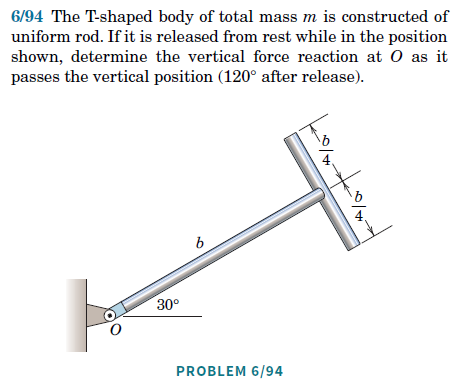

6/99, 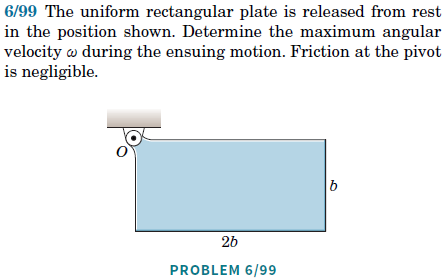

**6/100**